## Introduction

#### What is the main theme? Why is it important?

The purpose of this project is to study the impact of climate on glaciers through modeling the kinematics and mechanics of ice flow. It is important because glaciers are sensitive to slight changes in climate. We can infer past climate based on how glaciers molded landscapes and changed vegetation over time. To understand these changes, we need to understand how glaciers respond to changes in climate.

#### What observations, models, etc are used by others that are different from what you are doing in the project?

## Equations

#### What are the fundamental physical/chemical/etc. processes? 

This model is based on the concept that a glacier is a one-dimensional flow system which is continuously receiving or losing new material. **More glacier info??** We are modeling a kinematic wave equation as it pertains to ice flow. A wave in this sense refers to a point carrying a specified property (q) moving through a medium at a speed different than the medium itself.

#### Relevant equations and potentially where they come from (i.e. how are they derived)

Kinematic wave equation (eqn 4 in Nye 1960)

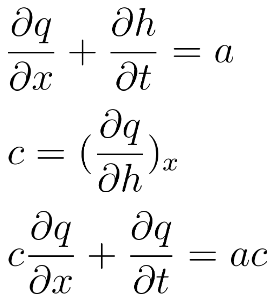

this is the surface slope as a function of (x, t) downhill in x direction beta is the slope of inclination


$$\[ \alpha = \beta - \frac{\partial{h}}{\partial{x}} \]$$


the paper also defines a value for u- this value is based on a  pre established tou value of rho*g*sin(alpha)


$$\[ u = \frac{\rho g h sin(\alpha)} {A}^{m} \]$$


where rho is density, h is height, g is gravity and alpha is the same as defined above.

the paper also defines at a(x,t) based on seaonal and or climate driven accumulation


$$\[ a(x,t) = a_0(x) + a_1(x,t) \]$$


they go on to say that a0 will be the avergaed rate of accumulation over a full year(net accumulation) and a1 will be the departure from a0(produced by seaonal or climatic changes

#### Describe all terms and parameters. 

q = volume of ice passing a given point in unit time (1 / unit breadth)

a = accumulation rate at surface (positive = addition of ice due to snowfall or avalanche, negative = melting or evaporation of ice)

c = velocity (but not velocity of the ice itself, which is u = q/h)

#### Describe any assumptions being made

We assume the volume and velocity (c) of the glacier are constant. Some simulations run assume accumulation is constant, and some assume accumulation oscillates a sine function throughout the year.

## Numerical Methods

#### Describe the numerical methods used.

Forward Euler

#### Why did you choose to use these methods

len =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51


a_rate = -5.0000e-06

div = 365

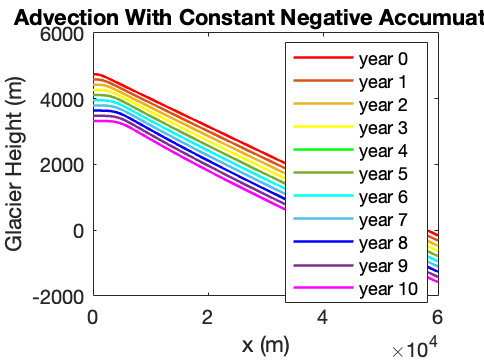

% Forward Euler

% we assume that spacial changes negligable
year = 24*365*60*60; %year in seconds
month = year/12;%month in seconds
day = 24*60*60;  % seconds in a day
dt = day;
tf = 10*year; %time frame and also time final running 10 years
nt = tf/dt; %number of time steps
t = linspace(0,tf,nt);
a_init = .000005; %m/s

a_rate = a_init.*sin((t)); 
a_rate2 = a_init.*3*sin((t.*8)); 


H = Up_euler(-.000005, "Constant Negative");

len =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51


a_rate = 5.0000e-06

div = 365

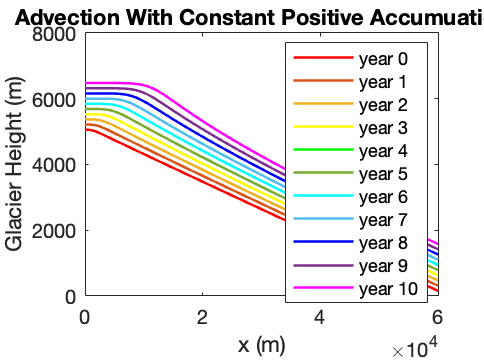

H = Up_euler(.000005, "Constant Positive");

len =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51


a_rate = 	1.0e+-5 *

         0   -0.4997   -0.0346    0.4973    0.0690   -0.4925   -0.1031    0.4854    0.1367   -0.4759   -0.1696    0.4642    0.2018   -0.4502   -0.2329    0.4341    0.2630   -0.4159   -0.2918    0.3957    0.3192   -0.3736   -0.3450    0.3497    0.3692   -0.3242   -0.3917    0.2971    0.4122   -0.2685   -0.4308    0.2387    0.4473   -0.2077   -0.4617    0.1758    0.4739   -0.1430   -0.4838    0.1095    0.4914   -0.0755   -0.4966    0.0411    0.4994   -0.0065   -0.4999   -0.0281    0.4979    0.0625


div = 365

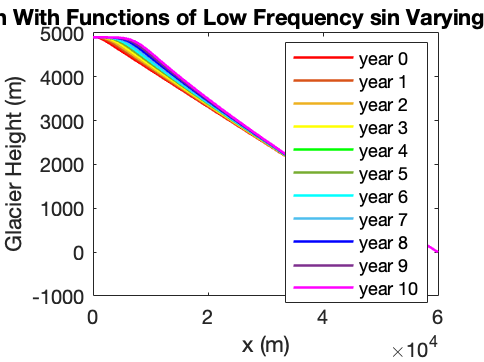


H = Up_euler_sin(a_rate, "Functions of Low Frequency sin Varying");

len =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51


a_rate = 	1.0e+-4 *

         0    0.0410    0.0789    0.1108    0.1342    0.1474    0.1494    0.1400    0.1199    0.0907    0.0546    0.0143   -0.0271   -0.0664   -0.1006   -0.1272   -0.1441   -0.1500   -0.1445   -0.1279   -0.1017   -0.0676   -0.0284    0.0129    0.0533    0.0896    0.1191    0.1395    0.1493    0.1477    0.1348    0.1117    0.0801    0.0423    0.0014   -0.0397   -0.0777   -0.1098   -0.1336   -0.1471   -0.1495   -0.1405   -0.1207   -0.0918   -0.0559   -0.0157    0.0257    0.0651    0.0996    0.1265


div = 365

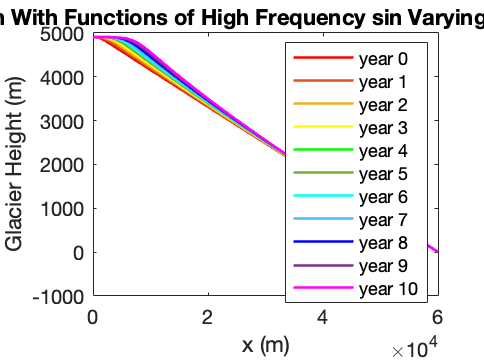

H = Up_euler_sin(a_rate2, "Functions of High Frequency sin Varying");




% accumulation, we will run accumulation using 2 constant cases, one
% positive and one negative, and one with seasonal change


function [H] = Up_euler(a, a_title)

%parameters
rho = 917;          % ice density kg/m^3
g = 9.81;             % gravity (m/s^2)
m = 3;                % constant from autumns last paper
A = 7*10^6;          % basal roughness, ask for value
beta = 1.5*10^-3;   %slope
alpha = beta;       %bed slope--> 

%time
year = 24*365*60*60; %year in seconds
month = year/12;%month in seconds
day = 24*60*60;  % seconds in a day
dt = day;
tf = 10*year; %time frame and also time final running 10 years
nt = tf/dt; %number of time steps
t = linspace(0,tf,nt);

%grid spacing
dx = 100; %meters, size of grid step
glacier_length = 60000; %length of our mountain glacier
x = linspace(0, glacier_length,dx);
nx = length(x);

%H initial!
len = 2:nx
h_init = 5000; %m
H = nan(nx,nt); 
H(2:end,1) = h_init - len.*(h_init/nx);  %this makes our glacier height linearly decline to 0!
H(1,1) = h_init; 

%accumulation
a_rate = a

for k = 1:nt-1


    %calulating U for each time step
    u = ((rho.*g.*H(:,k).*(alpha)).^m)./(A.^m);
%     Hprev = H(:,k);
%     H(:,k+1) = E_upwind(Hprev,dt,dx,u,a_rate(k));
    %setting up the M matrix
    M = spdiags([u*dt/dx.*ones(nx,1),1-(u*dt/dx).*ones(nx,1)],-1:0,nx,nx);
    %boundary conditions
    %height goes to 0 at the end of the glacier
    %we need an initial condition
    %set u value each time from last u value calculated
    
    M(end,end) = 1;
    M(end,end-1) = 0;
    M(1,1) = 0;
    M(1,2) = 1;

    H(:,k+1) = M*H(:,k)+a_rate*dt;
    %-a*v*dt
end
div = nt/10
%plot(t, H)

figure
plot(x, H(:,div),'r','LineWidth', 1.25)
hold on
plot(x, H(:,div*2),'color',"#D95319",'LineWidth', 1.25)
plot(x, H(:,div*3),'color',"#EDB120",'LineWidth', 1.25)
plot(x, H(:,div*4),'y','LineWidth', 1.25)
plot(x, H(:,div*5),'g','LineWidth', 1.25)
plot(x, H(:,div*5),'color',"#77AC30",'LineWidth', 1.25)
plot(x, H(:,div*6),'c','LineWidth', 1.25)
plot(x, H(:,div*7),'Color',	"#4DBEEE",'LineWidth', 1.25)
plot(x, H(:,div*8),'b','LineWidth', 1.25)
plot(x, H(:,div*9),'color',"#7E2F8E",'LineWidth', 1.25)
plot(x, H(:,div*10),'m','LineWidth', 1.25)
xlabel('x (m)')
ylabel('Glacier Height (m)')
title('Advection With ' +a_title+ ' Accumuation' )
legend('year 0','year 1','year 2','year 3','year 4','year 5','year 6','year 7','year 8','year 9','year 10')
hold off


%checking to make sure that our matrix is correct
j = full(M);

end


function [H] = Up_euler_sin(a, a_title)

%parameters
rho = 917;          % ice density kg/m^3
g = 9.81;             % gravity (m/s^2)
m = 3;                % constant from autumns last paper
A = 7*10^6;          % basal roughness, ask for value
beta = 1.5*10^-3;   %slope
alpha = beta;       %bed slope--> 

%time
year = 24*365*60*60; %year in seconds
month = year/12;%month in seconds
day = 24*60*60;  % seconds in a day
dt = day;
tf = 10*year; %time frame and also time final running 10 years
nt = tf/dt; %number of time steps
t = linspace(0,tf,nt);

%grid spacing
dx = 100; %meters, size of grid step
glacier_length = 60000; %length of our mountain glacier
x = linspace(0, glacier_length,dx);
nx = length(x);

%H initial!
len = 2:nx
h_init = 5000; %m
H = nan(nx,nt); 
H(2:end,1) = h_init - len.*(h_init/nx);  %this makes our glacier height linearly decline to 0!
H(1,1) = h_init; 

%accumulation
a_rate = a

for k = 1:nt-1


    %calulating U for each time step
    u = ((rho.*g.*H(:,k).*(alpha)).^m)./(A.^m);
%     Hprev = H(:,k);
%     H(:,k+1) = E_upwind(Hprev,dt,dx,u,a_rate(k));
    %setting up the M matrix
    M = spdiags([u*dt/dx.*ones(nx,1),1-(u*dt/dx).*ones(nx,1)],-1:0,nx,nx);
    %boundary conditions
    %height goes to 0 at the end of the glacier
    %we need an initial condition
    %set u value each time from last u value calculated
    
    M(end,end) = 1;
    M(end,end-1) = 0;
    M(1,1) = 0;
    M(1,2) = 1;

    H(:,k+1) = M*H(:,k)+a_rate(k)*dt;
    %-a*v*dt
end
div = nt/10
%plot(t, H)
%xlabel('Time (s)');ylabel('Glacier Height (m)')
figure
plot(x, H(:,div),'r','LineWidth', 1.25)
hold on
plot(x, H(:,div*2),'color',"#D95319",'LineWidth', 1.25)
plot(x, H(:,div*3),'color',"#EDB120",'LineWidth', 1.25)
plot(x, H(:,div*4),'y','LineWidth', 1.25)
plot(x, H(:,div*5),'g','LineWidth', 1.25)
plot(x, H(:,div*5),'color',"#77AC30",'LineWidth', 1.25)
plot(x, H(:,div*6),'c','LineWidth', 1.25)
plot(x, H(:,div*7),'Color',	"#4DBEEE",'LineWidth', 1.25)
plot(x, H(:,div*8),'b','LineWidth', 1.25)
plot(x, H(:,div*9),'color',"#7E2F8E",'LineWidth', 1.25)
plot(x, H(:,div*10),'m','LineWidth', 1.25)
xlabel('x (m)')
ylabel('Glacier Height (m)')
title('Advection With ' +a_title+ ' Accumuation' )
legend('year 0','year 1','year 2','year 3','year 4','year 5','year 6','year 7','year 8','year 9','year 10')
hold off


%checking to make sure that our matrix is correct
j = full(M);

end

## Results

#### What simulations did you run with the model?

Changed accumulation from constant to sin function (seasonal changes)

#### Describe the results.

#### How do the results compare with any known solutions, or data?

#### How do the results change with different methods, time steps, grid spacing, or model parameters?

#### What did the model tell you about the process you were studying?

#### How could the model be improved in terms of methods used or processes included?